clc ; clear all
syms theta1 theta2 theta3 theta4 theta5 theta6 ;

alpha = [0 0 0 0 45 90] ; 
a = [0 40 30 0 0 0] ; 
d = [0 0 0 10 10 50] ;
theta1 = 25 ;
theta2 = 0 ;
theta3 = 45 ;
theta4 = 0 ;
theta5 = 0 ;
theta6 = 20 ;
theta = [theta1 theta2 theta3 theta4 theta5 theta6 ]

theta =     25     0    45     0     0    20



T0_1 = T_matrix(theta1,alpha(1),a(1),d(1)) ;
T1_2 = T_matrix(theta2,alpha(2),a(2),d(2)) ;
T2_3 = T_matrix(theta3,alpha(3),a(3),d(3)) ;
T3_4 = T_matrix(theta4,alpha(4),a(4),d(4)) ;
T4_5 = T_matrix(theta5,alpha(4),a(4),d(4)) ;
T5_6 = T_matrix(theta6,alpha(5),a(5),d(5)) ;
T0_6 = @(theta1,theta2,theta3,theta4,theta5,theta6)T0_1*T1_2*T2_3*T3_4*T4_5*T5_6 

T0_6 = function_handle with value:
    @(theta1,theta2,theta3,theta4,theta5,theta6)T0_1*T1_2*T2_3*T3_4*T4_5*T5_6





%Printing out the DH Table
fprintf('DH TABLE: ')

DH TABLE: 

fprintf('%10s%10s%10s%15s\n', 'Theta', 'd', 'a', 'alpha');

     Theta         d         a          alpha


fprintf('%10d%+10.2f%+10.2f%+15.2f\n', theta(1) , d(1), a(1), alpha(1));

        25     +0.00     +0.00          +0.00


fprintf('%10d%+10.2f%+10.2f%+15.2f\n', theta(2) , d(2), a(2), alpha(2));

         0     +0.00    +40.00          +0.00


fprintf('%10d%+10.2f%+10.2f%+15.2f\n', theta(3) , d(3), a(3), alpha(3));

        45     +0.00    +30.00          +0.00


fprintf('%10d%+10.2f%+10.2f%+15.2f\n', theta(4) , d(4), a(4), alpha(4));

         0    +10.00     +0.00          +0.00


fprintf('%10d%+10.2f%+10.2f%+15.2f\n', theta(5) , d(5), a(5), alpha(5));

         0    +10.00     +0.00         +45.00


fprintf('%10d%+10.2f%+10.2f%+15.2f\n', theta(6) , d(6), a(6), alpha(6));

        20    +50.00     +0.00         +90.00


%VISUALISATION

%Since the size of the frames were too small, the parameters a and d were
%divided by 100, to better visualise the frames

dhparams= transpose([a/100 ; alpha; d/100 ; theta]) ;
robot = rigidBodyTree

robot =   rigidBodyTree with properties:

     NumBodies: 0
        Bodies: {1×0 cell}
          Base: [1×1 rigidBody]
     BodyNames: {1×0 cell}
      BaseName: 'base'
       Gravity: [0 0 0]
    DataFormat: 'struct'


body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');

setFixedTransform(jnt1,dhparams(1,:),'dh');
body1.Joint = jnt1;

addBody(robot,body1,'base')

body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
body3 = rigidBody('body3');
jnt3 = rigidBodyJoint('jnt3','revolute');
body4 = rigidBody('body4');
jnt4 = rigidBodyJoint('jnt4','revolute');
body5 = rigidBody('body5');
jnt5 = rigidBodyJoint('jnt5','revolute');
body6 = rigidBody('body6');
jnt6 = rigidBodyJoint('jnt6','revolute');

setFixedTransform(jnt2,dhparams(2,:),'dh');
setFixedTransform(jnt3,dhparams(3,:),'dh');
setFixedTransform(jnt4,dhparams(4,:),'dh');
setFixedTransform(jnt5,dhparams(5,:),'dh');
setFixedTransform(jnt6,dhparams(6,:),'dh');

body2.Joint = jnt2;
body3.Joint = jnt3;
body4.Joint = jnt4;
body5.Joint = jnt5;
body6.Joint = jnt6;

addBody(robot,body2,'body1')
addBody(robot,body3,'body2')
addBody(robot,body4,'body3')
addBody(robot,body5,'body4')
addBody(robot,body6,'body5')

showdetails(robot) ;

--------------------
Robot: (6 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3     revolute            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   body5(5)  
   5        body5         jnt5     revolute            body4(4)   body6(6)  
   6        body6         jnt6     revolute            body5(5)   
--------------------


show(robot, 'Frames', 'on') ;
f = gcf

f =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


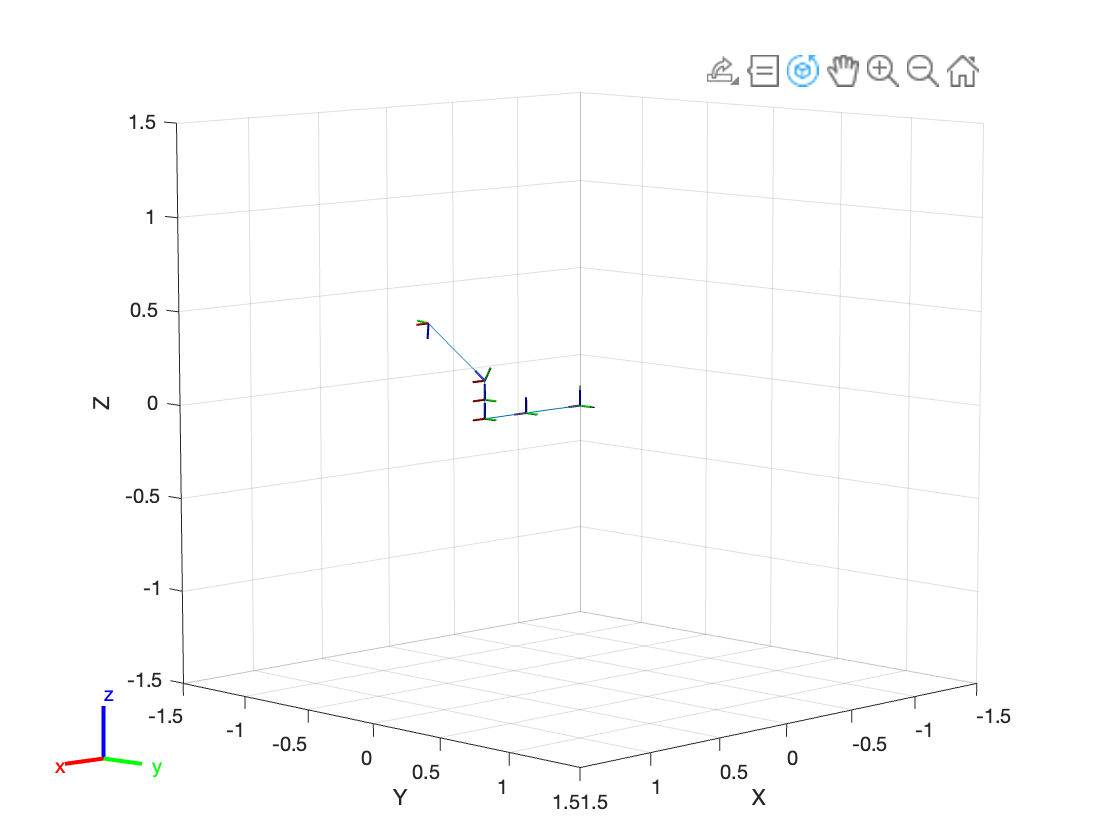

exportgraphics(f, "visualisation.jpg","Resolution", 500) ;

function T = T_matrix(theta,alpha,a,d) 
    T = [cos(theta) -cos(alpha)*sin(theta) sin(alpha)*sin(theta) a*cos(theta) ;
        sin(theta) cos(alpha)*cos(theta) -sin(alpha)*cos(theta) a*sin(theta) ;
        0 sin(alpha) cos(alpha) d ;
        0 0 0 1] ;
end

